# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_3_Data_Analysys

## Analyzing Return Distributions

In this activity, we analyze the daily returns of a representative large-cap stock to study how well the **Normal distribution** describes real financial data.

We compute daily returns from historical prices and visualize their empirical distribution.

We then compare this distribution with a theoretical Normal distribution using MATLAB's Distribution Fitter App.

This exercise illustrates that, although the Normal distribution is often used as a first approximation in finance, real return distributions typically exhibit fat tails and skewness.

These deviations from normality are crucial in risk management, as they imply a higher probability of extreme market movements than predicted by the Normal model.


% Define parameters
symbol = 'NVDA';                     % Stock symbol for Apple Inc.
startDate = '01-Jan-2020';           % Start date
endDate = '01-Oct-2025';             % End date
interval = '1d';                     % Data interval ('1d', '1wk', '1mo')
fields = {'close'}; %{'open', 'high', 'low', 'close', 'volume'};  % Fields to retrieve

% Fetch data
stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields);

% Display the first 10 rows
disp(stockData(1:10, :));

            Date            Close 
    ____________________    ______

    02-Jan-2020 14:30:00    5.9977
    03-Jan-2020 14:30:00    5.9018
    06-Jan-2020 14:30:00    5.9265
    07-Jan-2020 14:30:00    5.9983
    08-Jan-2020 14:30:00    6.0095
    09-Jan-2020 14:30:00    6.0755
    10-Jan-2020 14:30:00     6.108
    13-Jan-2020 14:30:00    6.2995
    14-Jan-2020 14:30:00     6.182
    15-Jan-2020 14:30:00    6.1392





Date=stockData.Date;

Price = stockData.Close;

Plot prices, returns and frequency distribution of returns:

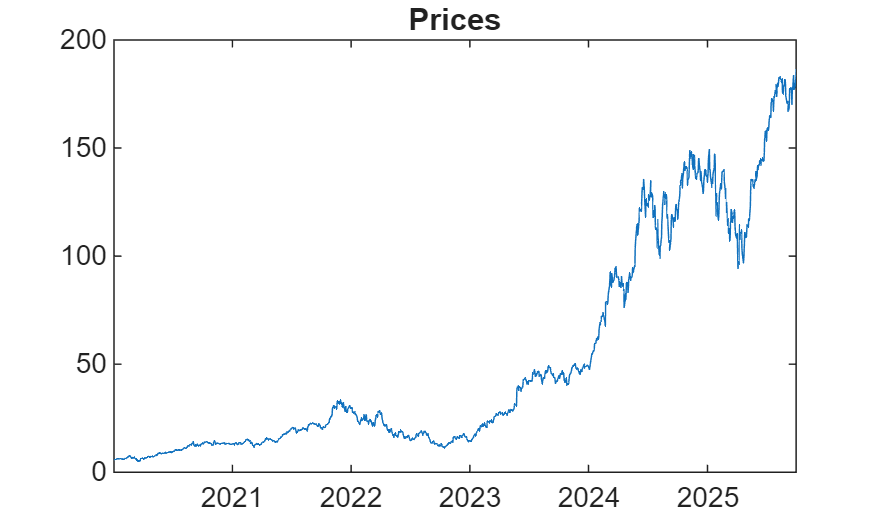


figure;
plot(Date,Price);
title('Prices')

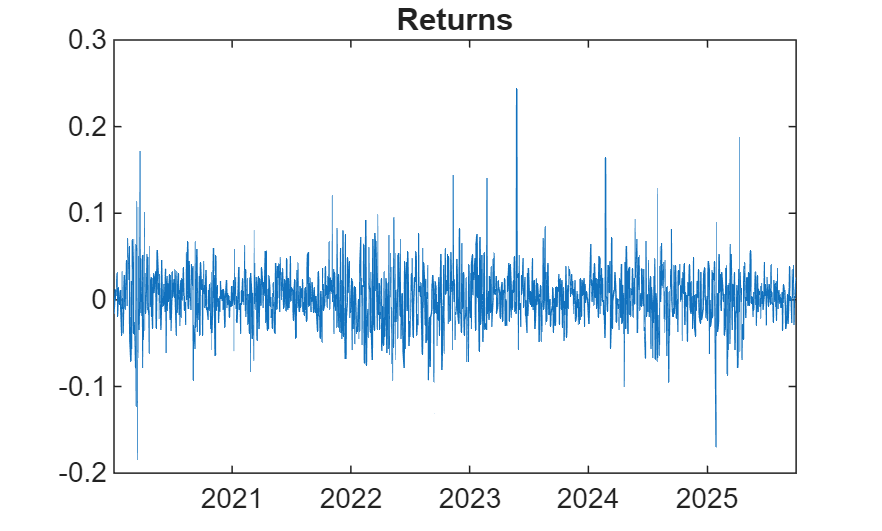

returns = tick2ret(Price);
figure;
plot(Date(2:end),returns)
title('Returns')

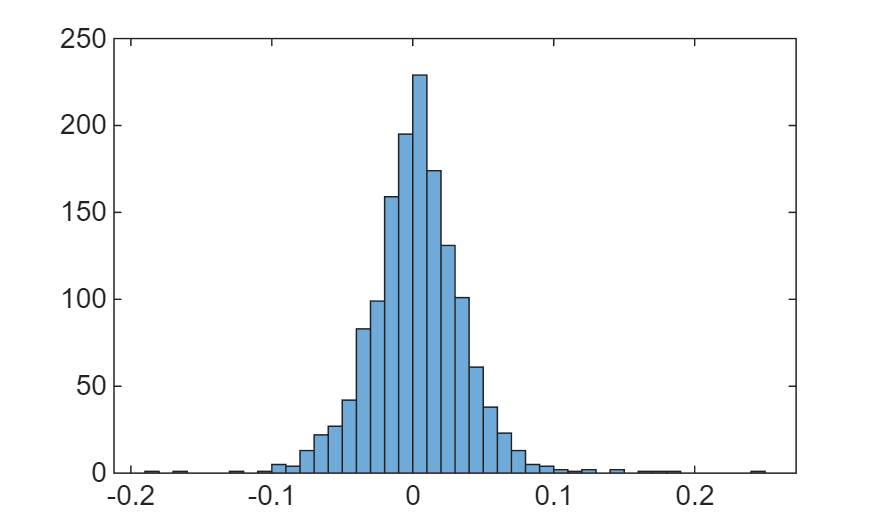

figure;
histogram(returns);

Now, we use MATLAB's Distribution Fitter App.

The app allows us to interactively fit a theoretical distribution — in this case, the Normal distribution — to the empirical data and visually assess how well it represents real financial returns.

Once the best-fitting parameters (mean and standard deviation) are estimated, MATLAB can automatically generate a corresponding probability density function (PDF).

This function can then be exported from the app and called directly in the code, enabling comparison between the empirical histogram and the fitted Normal curve.

The steps are:

- **Load the returns** into the Distribution Fitter App by choosing the variable Returns, and then click on **Create Data Set. **Click **New Fit**, choose the **Normal** distribution, and generate the fitted curve.

- From the app, select **File → Generate Function** to create MATLAB code that reproduces the same fitted model.

- Place the generated function **at the end of this live file** (or save it on the MATLAB path).

- In the main script, **call the generated function** to retrieve the fitted parameters and overlay the **Normal PDF** on the empirical histogram.

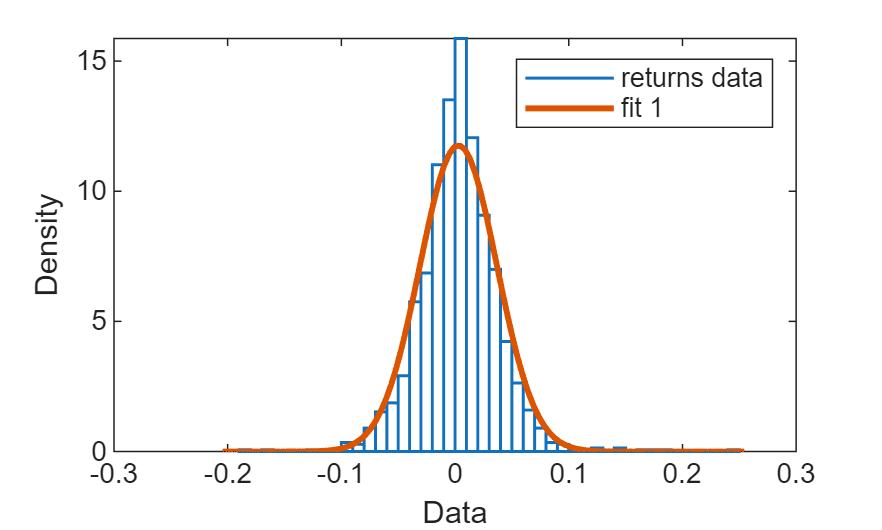

ans =   NormalDistribution

  Normal distribution
       mu = 0.00295503   [0.00120473, 0.00470533]
    sigma =  0.0338947   [0.0327017, 0.0351788]


createFit(returns)

This workflow demonstrates how to integrate MATLAB's interactive tools with script-based analysis, and highlights that real-world return distributions often deviate from normality, showing fat tails and asymmetry that are critical for understanding financial risk.

**Further Exploration: Aggregational Gaussianity**

An interesting extension of this analysis is to explore the concept of **aggregational Gaussianity**.

This phenomenon refers to the tendency of return distributions to become **more Gaussian** as the sampling frequency decreases — for example, when moving from daily to weekly or monthly returns.

You can test this by recomputing returns at a **lower frequency** (e.g., monthly) and repeating the same fitting procedure.

You will typically observe that extreme values become less pronounced and the fitted Normal distribution provides a better approximation, reflecting the **central limit effect** over longer time horizons.

function pd1 = createFit(returns)
%CREATEFIT    Create plot of datasets and fits
%   PD1 = CREATEFIT(RETURNS)
%   Creates a plot, similar to the plot in the main distribution fitter
%   window, using the data that you provide as input.  You can
%   apply this function to the same data you used with distributionFitter
%   or with different data.  You may want to edit the function to
%   customize the code and this help message.
%
%   Number of datasets:  1
%   Number of fits:  1
%
%   See also FITDIST.

% This function was automatically generated on 04-Oct-2025 16:28:12

% Output fitted probability distribution: PD1

% Data from dataset "returns data":
%    Y = returns

% Force all inputs to be column vectors
returns = returns(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "returns data"
[CdfF,CdfX] = ecdf(returns,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 6;
[~,BinEdge] = internal.stats.histbins(returns,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.066 0.443 0.745],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'returns data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);


% --- Create fit "fit 1"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = makedist('normal', mu=0.0005580091099658, sigma=0.01327327766969)
pd1 = fitdist(returns, 'normal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0.866 0.329 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');
end

function stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
% fetchYahooFinanceData Fetches historical stock data from Yahoo Finance.
%
%   stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
%
%   Parameters:
%       symbol     - Stock symbol as a string (e.g., 'AAPL').
%       startDate  - Start date as a string or datetime ('dd-mmm-yyyy' format).
%       endDate    - End date as a string or datetime ('dd-mmm-yyyy' format).
%       interval   - Data interval: '1d' (daily), '1wk' (weekly), '1mo' (monthly).
%       fields     - Cell array of strings -i.e.curly brackets needed to
%       enter input, specifying data fields to retrieve, one or more
%                    Valid fields: 'open', 'close', 'high', 'low',
%                    'volume'. e.g.{'open', 'high', 'low', 'close', 'volume'}, 
%
%   Returns:
%       stockData  - Table containing the date and requested data fields.

    % Validate inputs
    if nargin < 5
        error('All five arguments (symbol, startDate, endDate, interval, fields) are required.');
    end

    % Convert dates to datetime if necessary
    if ischar(startDate) || isstring(startDate)
        startDate = datetime(startDate, 'InputFormat', 'dd-MMM-yyyy');
    end
    if ischar(endDate) || isstring(endDate)
        endDate = datetime(endDate, 'InputFormat', 'dd-MMM-yyyy');
    end

    % Validate interval
    validIntervals = {'1d', '1wk', '1mo'};
    if ~ismember(interval, validIntervals)
        error('Invalid interval. Choose from ''1d'', ''1wk'', or ''1mo''.');
    end

    % Convert dates to UNIX timestamps
    startNum = posixtime(datetime(startDate));
    endNum = posixtime(datetime(endDate));

    % Construct the URL
    url = ['https://query1.finance.yahoo.com/v8/finance/chart/' symbol ...
           '?period1=' num2str(floor(startNum)) '&period2=' num2str(floor(endNum)) '&interval=' interval];

    % Set web options with a user-agent header to mimic a browser
    options = weboptions('ContentType', 'json', 'UserAgent', 'Mozilla/5.0');

    % Fetch data
    try
        data = webread(url, options);
    catch ME
        error('Failed to retrieve data: %s', ME.message);
    end

    % Check for errors in response
    if isempty(data.chart.result) || ~isempty(data.chart.error)
        error('Failed to retrieve data. Please check the stock symbol and date range.');
    end

    % Extract the result
    result = data.chart.result;
    if iscell(result)
        result = result{1};
    elseif isstruct(result) && numel(result) > 1
        result = result(1);
    end

    % Extract timestamps
    if isfield(result, 'timestamp')
        timestamps = result.timestamp;
    else
        error('No timestamp data available.');
    end

    % Convert timestamps to datetime
    dates = datetime(timestamps, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

    % Access indicators
    if isfield(result, 'indicators') && isfield(result.indicators, 'quote')
        quote = result.indicators.quote;
        if iscell(quote)
            quote = quote{1};
        elseif isstruct(quote) && numel(quote) > 1
            quote = quote(1);
        end
    else
        error('No quote data available.');
    end

    % Initialize table with dates
    stockData = table(dates, 'VariableNames', {'Date'});

    % Ensure fields are in lowercase
    fields = lower(fields);

    % Valid fields in the data
    validFields = fieldnames(quote);

    % For each requested field, extract the data
    for i = 1:length(fields)
        field = fields{i};
        if ismember(field, validFields)
            fieldData = quote.(field);
            fieldData = fieldData(:);  % Ensure column vector
            % Handle missing data
            if length(fieldData) < length(dates)
                fieldData(end+1:length(dates)) = NaN;
            elseif length(fieldData) > length(dates)
                fieldData = fieldData(1:length(dates));
            end
            % Append to table with capitalized field name
            stockData.(capitalizeFirstLetter(field)) = fieldData;
        else
            warning('Field "%s" is not available in the data.', field);
            % Fill with NaNs if field is missing
            stockData.(capitalizeFirstLetter(field)) = NaN(height(stockData), 1);
        end
    end

    % Remove rows where all data fields are NaN
    dataFields = stockData.Properties.VariableNames(2:end);
    validRows = any(~isnan(stockData{:, dataFields}), 2);
    stockData = stockData(validRows, :);

    % Reset the datetime to remove time zone information
    stockData.Date.TimeZone = '';

end

function outStr = capitalizeFirstLetter(inStr)
% Helper function to capitalize the first letter of a string
    outStr = lower(inStr);
    if ~isempty(outStr)
        outStr(1) = upper(outStr(1));
    end
end

